clc;
clear;
close all;

%% ============================================================
% FULL FUSELAGE SHEAR FLOW + FULL BULKHEAD CASTIGLIANO ANALYSIS
%
% PART A:
%   Closed rectangular fuselage
%   4 corner longerons
%   Calculate shear flow q around fuselage
%
% PART B:
%   Extract calculated fuselage q over the 90 mm top panel
%   Use this q as the distributed bulkhead load
%
% PART C:
%   Bulkhead Castigliano analysis
%   Unknowns:
%       F4 = axial force at point 4
%       V4 = shear force at point 4
%       M4 = bending moment at point 4
%
%   Half bulkhead:
%
%             1
%             |
%       0.09  |
%             |
%             2
%             |
%       0.18  |
%             |
%             3
%             |
%       0.09  |
%             |
%             4
%
%   The reference report uses:
%
%       F(s), V(s), M(s)
%
%   and
%
%       U = Umoment + Ushear + Uaxial
%
%   with:
%
%       dU/dF4 = 0
%       dU/dV4 = 0
%       dU/dM4 = 0
%
% ============================================================


%% ============================================================
% PART A
% FUSELAGE SHEAR FLOW CALCULATION
% ============================================================


%% ---------------- INPUTS ----------------

Vy = -50;              % Vertical shear force [N]

b = 0.180;             % Fuselage width [m]
h = 0.250;             % Fuselage height [m]

t = 1e-3;              % Fuselage skin thickness [m]

A_L = 10e-6;           % Area of EACH longeron [m^2]
                       % = 10 mm^2

N = 300;               % Points per skin panel


%% ============================================================
% LONGERON LOCATIONS
% ============================================================

% 1 = top-left
% 2 = bottom-left
% 3 = bottom-right
% 4 = top-right

xB = [-b/2, -b/2,  b/2,  b/2];
yB = [ h/2, -h/2, -h/2,  h/2];


%% ============================================================
% SECOND MOMENT OF AREA
% ============================================================

% ---- Skin contribution ----

Ixx_skin = ...
      2*(b*t)*(h/2)^2 ...
    + 2*t*h^3/12;


% ---- Longerons contribution ----

Ixx_long = sum(A_L .* yB.^2);


% ---- Total ----

Ixx = Ixx_skin + Ixx_long;


%% ============================================================
% CREATE CLOSED SKIN CONTOUR
%
% CUT AT MIDDLE OF TOP PANEL
%
%        CUT
%         |
%   ------+------
%   |           |
%   |           |
%   |           |
%   -------------
%
% Travel clockwise.
% ============================================================


% Top-left half
x1 = linspace(0, -b/2, N);
y1 = (h/2)*ones(1,N);

% Left wall
x2 = (-b/2)*ones(1,N);
y2 = linspace(h/2, -h/2, N);

% Bottom wall
x3 = linspace(-b/2, b/2, N);
y3 = (-h/2)*ones(1,N);

% Right wall
x4 = (b/2)*ones(1,N);
y4 = linspace(-h/2, h/2, N);

% Top-right half
x5 = linspace(b/2, 0, N);
y5 = (h/2)*ones(1,N);


% Combine contour

x = [x1, ...
     x2(2:end), ...
     x3(2:end), ...
     x4(2:end), ...
     x5(2:end)];

y = [y1, ...
     y2(2:end), ...
     y3(2:end), ...
     y4(2:end), ...
     y5(2:end)];


x = x(:);
y = y(:);


%% ============================================================
% FUSELAGE SHEAR FLOW
%
% q_b = -(Vy/Ixx)*Q
%
% Q = integral(y*t*ds) + sum(A_i*y_i)
% ============================================================

qb = zeros(size(x));

Q_skin = 0;
Q_boom = 0;

boom_used = false(1,4);


for i = 2:length(x)

    % --------------------------------------------------------
    % Skin contribution
    % --------------------------------------------------------

    dx = x(i) - x(i-1);
    dy = y(i) - y(i-1);

    ds = sqrt(dx^2 + dy^2);

    y_avg = 0.5*(y(i-1) + y(i));

    dQ_skin = y_avg * t * ds;

    Q_skin = Q_skin + dQ_skin;


    % --------------------------------------------------------
    % Longeron contribution
    % --------------------------------------------------------

    for k = 1:4

        if ~boom_used(k)

            distance_to_boom = ...
                sqrt((x(i)-xB(k))^2 + ...
                     (y(i)-yB(k))^2);

            if distance_to_boom < ds*1.5

                Q_boom = Q_boom + A_L*yB(k);

                boom_used(k) = true;

            end
        end
    end


    % --------------------------------------------------------
    % Total first moment
    % --------------------------------------------------------

    Q = Q_skin + Q_boom;


    % --------------------------------------------------------
    % Basic shear flow
    % --------------------------------------------------------

    qb(i) = -(Vy/Ixx)*Q;

end


%% ============================================================
% CLOSED CELL CONSTANT SHEAR FLOW q0
%
% Compatibility:
%
%     integral(q/t ds) = 0
%
% ============================================================

int_qb_t = 0;
int_1_t  = 0;


for i = 2:length(x)

    dx = x(i)-x(i-1);
    dy = y(i)-y(i-1);

    ds = sqrt(dx^2 + dy^2);

    qb_avg = 0.5*(qb(i-1)+qb(i));

    int_qb_t = int_qb_t + qb_avg/t*ds;

    int_1_t = int_1_t + ds/t;

end


q0 = -int_qb_t/int_1_t;


%% ============================================================
% TOTAL FUSELAGE SHEAR FLOW
% ============================================================

q = qb + q0;


%% ============================================================
% DISTANCE ALONG FUSELAGE PERIMETER
% ============================================================

s_fuse = zeros(size(x));


for i = 2:length(x)

    ds = sqrt( ...
        (x(i)-x(i-1))^2 + ...
        (y(i)-y(i-1))^2 );

    s_fuse(i) = s_fuse(i-1) + ds;

end


%% ============================================================
% FUSELAGE RESULTS
% ============================================================

fprintf('\n');
fprintf('====================================================\n');

fprintf('       PART A - FUSELAGE SHEAR FLOW\n');

       PART A - FUSELAGE SHEAR FLOW


fprintf('====================================================\n');


fprintf('\nLoads:\n');


Loads:


fprintf('Vy                    = %.3f N\n',Vy);

Vy                    = -50.000 N



fprintf('\nGeometry:\n');


Geometry:


fprintf('Width                 = %.1f mm\n',b*1000);

Width                 = 180.0 mm


fprintf('Height                = %.1f mm\n',h*1000);

Height                = 250.0 mm


fprintf('Skin thickness        = %.2f mm\n',t*1000);

Skin thickness        = 1.00 mm



fprintf('\nLongerons:\n');


Longerons:


fprintf('Area of each          = %.2f mm^2\n',A_L*1e6);

Area of each          = 10.00 mm^2


fprintf('Number                = 4\n');

Number                = 4



fprintf('\nSecond moments:\n');


Second moments:


fprintf('Ixx skin              = %.6e m^4\n',Ixx_skin);

Ixx skin              = 8.229167e-06 m^4


fprintf('Ixx longerons         = %.6e m^4\n',Ixx_long);

Ixx longerons         = 6.250000e-07 m^4


fprintf('Ixx total             = %.6e m^4\n',Ixx);

Ixx total             = 8.854167e-06 m^4



fprintf('\nClosed-cell correction:\n');


Closed-cell correction:


fprintf('q0                    = %.6f N/m\n',q0);

q0                    = 0.003706 N/m



fprintf('\nShear flow:\n');


Shear flow:


fprintf('qb,max                = %.6f N/m\n',max(qb));

qb,max                = 114.705389 N/m


fprintf('qb,min                = %.6f N/m\n',min(qb));

qb,min                = -114.705389 N/m



fprintf('q,max                 = %.6f N/m\n',max(q));

q,max                 = 114.709095 N/m


fprintf('q,min                 = %.6f N/m\n',min(q));

q,min                 = -114.701683 N/m



fprintf('abs(q)_max            = %.6f N/m\n',max(abs(q)));

abs(q)_max            = 114.709095 N/m



fprintf('====================================================\n');



%% ============================================================
% PART B
% EXTRACT BULKHEAD LOAD FROM YOUR FUSELAGE q
% ============================================================
%
% The reference bulkhead has 90 mm end members.
%
% We use the first 90 mm of your contour:
%
%        TOP CENTRE
%             |
%             |
%       90 mm TOP PANEL
%             |
%        TOP LEFT CORNER
%
% This q is taken directly from the calculation above.
%
% ============================================================


%% ---------------- Identify top-left panel ----------------

tol = 1e-10;

%% ============================================================
% EXTRACT TOP-LEFT HALF OF FUSELAGE CONTOUR
% ============================================================
%
% The contour was created as:
%
% x1 = linspace(0,-b/2,N);
%
% Therefore the first N points are exactly the
% top-left half-panel.
%
% This avoids the duplicated cut point x = 0.
% ============================================================

x_top = x(1:N);
q_top = q(1:N);

% Distance measured from the cut at x = 0
s_top = abs(x_top);

% Make sure the data runs from s = 0 --> b/2
[s_top,idx_sort] = sort(s_top);

q_top = q_top(idx_sort);
x_top = x_top(idx_sort);


%% ============================================================
% INTERPOLATE YOUR CALCULATED q TO BULKHEAD MEMBER
% ============================================================

Nbh = 1000;

L1 = 0.09;
L2 = 0.18;
L3 = 0.09;

s1 = linspace(0,L1,Nbh);
s2 = linspace(0,L2,Nbh);
s3 = linspace(0,L3,Nbh);


%% ============================================================
% YOUR FUSELAGE q BECOMES BULKHEAD DISTRIBUTED LOAD
% ============================================================

q_bh = interp1( ...
    s_top, ...
    q_top, ...
    s3, ...
    'pchip');


%% ============================================================
% DISPLAY EXTRACTED BULKHEAD LOAD
% ============================================================

fprintf('\n');
fprintf('====================================================\n');

fprintf('       PART B - BULKHEAD LOAD FROM YOUR q\n');

       PART B - BULKHEAD LOAD FROM YOUR q


fprintf('====================================================\n');


fprintf('\nBulkhead load is NOT hard-coded.\n');


Bulkhead load is NOT hard-coded.


fprintf('It is extracted directly from fuselage shear flow.\n');

It is extracted directly from fuselage shear flow.



fprintf('\nExtracted panel length = %.3f mm\n', ...
    max(s_top)*1000);


Extracted panel length = 90.000 mm



fprintf('q at panel start       = %.6f N/m\n',q_top(1));

q at panel start       = 0.003706 N/m



fprintf('q at panel end         = %.6f N/m\n',q_top(end));

q at panel end         = 70.591941 N/m



fprintf('q maximum on panel     = %.6f N/m\n',max(q_top));

q maximum on panel     = 70.591941 N/m



fprintf('q minimum on panel     = %.6f N/m\n',min(q_top));

q minimum on panel     = 0.003706 N/m



fprintf('====================================================\n');

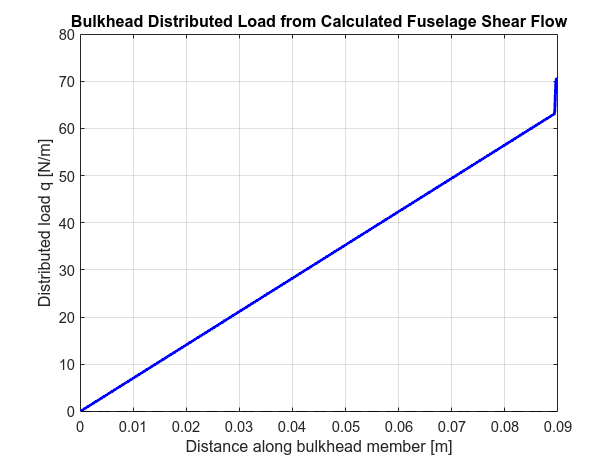






%% ============================================================
% CALCULATE
%
% Qq(s) = integral q(x) dx
%
% Mq(s) = integral q(x)(s-x) dx
% ============================================================


Qq = cumtrapz(s3,q_bh);


Mq = zeros(size(s3));


for j = 1:length(s3)

    if j == 1

        Mq(j) = 0;

    else

        Mq(j) = trapz( ...
            s3(1:j), ...
            q_bh(1:j).*(s3(j)-s3(1:j)) );

    end

end


%% ============================================================
% PLOT THE ACTUAL q USED BY BULKHEAD
% ============================================================

figure('Color','w');

plot(s3,q_bh,'b-','LineWidth',2);

grid on;
box on;

xlabel('Distance along bulkhead member [m]');
ylabel('Distributed load q [N/m]');

title('Bulkhead Distributed Load from Calculated Fuselage Shear Flow');

yline(0,'k--');



%% ============================================================
% PART C
% CASTIGLIANO BULKHEAD ANALYSIS
% ============================================================


%% ============================================================
% MATERIAL AND SECTION PROPERTIES
% ============================================================

E = 70e9;       % Young modulus [Pa]
G = 26e9;       % Shear modulus [Pa]


% Reference report values
%
% I = (0.09^3*0.0005)/3
%     + (0.09*0.0005^3)/12
%
% A = 4*0.09*0.0005
%
% As = (10*0.09*0.0005)/3
%
% These are retained from Appendix C.3.

t_member = 0.0005;


I_member = ...
    (0.09^3*t_member)/3 ...
    + ...
    (0.09*t_member^3)/12;


A_member = ...
    4*0.09*t_member;


As_member = ...
    (10*0.09*t_member)/3;


fprintf('\n');
fprintf('====================================================\n');

fprintf('       PART C - CASTIGLIANO BULKHEAD\n');

       PART C - CASTIGLIANO BULKHEAD


fprintf('====================================================\n');


fprintf('\nMaterial:\n');


Material:


fprintf('E                     = %.3e Pa\n',E);

E                     = 7.000e+10 Pa


fprintf('G                     = %.3e Pa\n',G);

G                     = 2.600e+10 Pa



fprintf('\nReference member properties:\n');


Reference member properties:


fprintf('I                     = %.6e m^4\n',I_member);

I                     = 1.215009e-07 m^4


fprintf('A                     = %.6e m^2\n',A_member);

A                     = 1.800000e-04 m^2


fprintf('As                    = %.6e m^2\n',As_member);

As                    = 1.500000e-04 m^2




%% ============================================================
% IMPORTANT:
%
% The report uses the following internal force equations:
%
% Section 1:
%
% F1 = F4 - 744.4*s^2
% V1 = -V4
% M1 = M4 + V4*s
%
% Section 2:
%
% F2 = -V4
%      +2145*s^3
%      -579.16*s^2
%      -148.89*s
%
% V2 = -F4 + 6.03
%
% M2 = -M4
%      -0.09*V4
%      +F4*s
%      -6.03*s
%
% Section 3:
%
% F3 = -F4
%      +6.03
%      -744.44*s^2
%      +134*s
%
% V3 = V4
%      -5.04
%      + integral(q dx)
%      -9.81*s
%
% M3 = M4
%      +V4*(0.09-s)
%      -0.18*F4
%      -14.786
%      +1.09
%      +5.04*s
%      - integral(q*(s-x) dx)
%      +0.5*9.81*s^2
%
% The ONLY change from the report is:
%
%       q = YOUR FUSELAGE SHEAR FLOW
%
% ============================================================


%% ============================================================
% CASTIGLIANO SOLUTION
%
% Instead of symbolic integration, construct the quadratic
% strain energy numerically.
%
% Let
%
%       z = [F4 V4 M4]'
%
% Each internal force has the form:
%
%       F(s) = a_F(s)*z + f0(s)
%
%       V(s) = a_V(s)*z + v0(s)
%
%       M(s) = a_M(s)*z + m0(s)
%
% Since U is quadratic in z,
%
%       U = 1/2*z'*K*z + r'*z + C
%
% and Castigliano gives:
%
%       K*z + r = 0
%
% hence
%
%       z = -K\r
%
% ============================================================


%% ============================================================
% SECTION 1
% ============================================================

% F1 = F4 - 744.4*s^2

AF1 = [ ...
    ones(size(s1)); ...
    zeros(size(s1)); ...
    zeros(size(s1))];


f01 = -744.4*s1.^2;


% V1 = -V4

AV1 = [ ...
    zeros(size(s1)); ...
    -ones(size(s1)); ...
    zeros(size(s1))];


v01 = zeros(size(s1));


% M1 = M4 + V4*s

AM1 = [ ...
    zeros(size(s1)); ...
    s1; ...
    ones(size(s1))];


m01 = zeros(size(s1));


%% ============================================================
% SECTION 2
% ============================================================

% F2 =
% -V4
% +2145*s^3
% -579.16*s^2
% -148.89*s

AF2 = [ ...
    zeros(size(s2)); ...
    -ones(size(s2)); ...
    zeros(size(s2))];


f02 = ...
    2145*s2.^3 ...
    -579.16*s2.^2 ...
    -148.89*s2;


% V2 = -F4 + 6.03

AV2 = [ ...
    -ones(size(s2)); ...
    zeros(size(s2)); ...
    zeros(size(s2))];


v02 = 6.03*ones(size(s2));


% M2 =
% -M4
% -0.09*V4
% +F4*s
% -6.03*s

AM2 = [ ...
    s2; ...
    -0.09*ones(size(s2)); ...
    -ones(size(s2))];


m02 = -6.03*s2;


%% ============================================================
% SECTION 3
% ============================================================

% F3 =
% -F4
% +6.03
% -744.44*s^2
% +134*s

AF3 = [ ...
    -ones(size(s3)); ...
    zeros(size(s3)); ...
    zeros(size(s3))];


f03 = ...
    6.03 ...
    -744.44*s3.^2 ...
    +134*s3;


% V3 =
% V4
% -5.04
% +Qq
% -9.81*s

AV3 = [ ...
    zeros(size(s3)); ...
    ones(size(s3)); ...
    zeros(size(s3))];


v03 = ...
    -5.04 ...
    +Qq ...
    -9.81*s3;


% M3 =
% M4
% +V4*(0.09-s)
% -0.18*F4
% -14.786
% +1.09
% +5.04*s
% -Mq
% +0.5*9.81*s^2

AM3 = [ ...
    -0.18*ones(size(s3)); ...
    0.09-s3; ...
    ones(size(s3))];


m03 = ...
    -14.786 ...
    +1.09 ...
    +5.04*s3 ...
    -Mq ...
    +0.5*9.81*s3.^2;


%% ============================================================
% BUILD STRAIN ENERGY MATRIX
% ============================================================

K = zeros(3,3);
r = zeros(3,1);


% ------------------------------------------------------------
% Function for one section
%
% U = integral[
%
%       M^2/(2EI)
%     + V^2/(2GAs)
%     + F^2/(2EA)
%
% ] ds
% ------------------------------------------------------------


%% ============================================================
% SECTION 1 ENERGY
% ============================================================

% ---- Bending ----

K = K + ...
    trapz(s1, ...
    (AM1'*AM1)/(E*I_member));

Arrays have incompatible sizes for this operation.

Related documentation



r = r + ...
    trapz(s1, ...
    AM1*m01, ...
    2);


% ---- Shear ----

K = K + ...
    trapz(s1, ...
    (AV1'*AV1)/(G*As_member));


r = r + ...
    trapz(s1, ...
    AV1*v01, ...
    2);


% ---- Axial ----

K = K + ...
    trapz(s1, ...
    (AF1'*AF1)/(E*A_member));


r = r + ...
    trapz(s1, ...
    AF1*f01, ...
    2);


%% ============================================================
% SECTION 2 ENERGY
% ============================================================

% ---- Bending ----

K = K + ...
    trapz(s2, ...
    (AM2'*AM2)/(E*I_member));


r = r + ...
    trapz(s2, ...
    AM2*m02, ...
    2);


% ---- Shear ----

K = K + ...
    trapz(s2, ...
    (AV2'*AV2)/(G*As_member));


r = r + ...
    trapz(s2, ...
    AV2*v02, ...
    2);


% ---- Axial ----

K = K + ...
    trapz(s2, ...
    (AF2'*AF2)/(E*A_member));


r = r + ...
    trapz(s2, ...
    AF2*f02, ...
    2);


%% ============================================================
% SECTION 3 ENERGY
% ============================================================

% ---- Bending ----

K = K + ...
    trapz(s3, ...
    (AM3'*AM3)/(E*I_member));


r = r + ...
    trapz(s3, ...
    AM3*m03, ...
    2);


% ---- Shear ----

K = K + ...
    trapz(s3, ...
    (AV3'*AV3)/(G*As_member));


r = r + ...
    trapz(s3, ...
    AV3*v03, ...
    2);


% ---- Axial ----

K = K + ...
    trapz(s3, ...
    (AF3'*AF3)/(E*A_member));


r = r + ...
    trapz(s3, ...
    AF3*f03, ...
    2);


%% ============================================================
% SOLVE CASTIGLIANO EQUATIONS
%
% dU/dF4 = 0
% dU/dV4 = 0
% dU/dM4 = 0
%
% gives:
%
% K*[F4 V4 M4]' + r = 0
%
% ============================================================

solution = -K\r;


F4_sol = solution(1);
V4_sol = solution(2);
M4_sol = solution(3);


%% ============================================================
% PRINT CASTIGLIANO RESULTS
% ============================================================

fprintf('\n');
fprintf('Unknown actions at Point 4:\n');

fprintf('F4 = %.6f N\n',F4_sol);
fprintf('V4 = %.6f N\n',V4_sol);
fprintf('M4 = %.6f N-m\n',M4_sol);

fprintf('\nMagnitudes:\n');

fprintf('|F4| = %.6f N\n',abs(F4_sol));
fprintf('|V4| = %.6f N\n',abs(V4_sol));
fprintf('|M4| = %.6f N-m\n',abs(M4_sol));


%% ============================================================
% SUBSTITUTE THE SOLUTION
% AND CALCULATE INTERNAL FORCES
% ============================================================


%% ---------------- SECTION 1 ----------------

F1_final = ...
    AF1(1,:)*F4_sol ...
    + AF1(2,:)*V4_sol ...
    + AF1(3,:)*M4_sol ...
    + f01;


V1_final = ...
    AV1(1,:)*F4_sol ...
    + AV1(2,:)*V4_sol ...
    + AV1(3,:)*M4_sol ...
    + v01;


M1_final = ...
    AM1(1,:)*F4_sol ...
    + AM1(2,:)*V4_sol ...
    + AM1(3,:)*M4_sol ...
    + m01;


%% ---------------- SECTION 2 ----------------

F2_final = ...
    AF2(1,:)*F4_sol ...
    + AF2(2,:)*V4_sol ...
    + AF2(3,:)*M4_sol ...
    + f02;


V2_final = ...
    AV2(1,:)*F4_sol ...
    + AV2(2,:)*V4_sol ...
    + AV2(3,:)*M4_sol ...
    + v02;


M2_final = ...
    AM2(1,:)*F4_sol ...
    + AM2(2,:)*V4_sol ...
    + AM2(3,:)*M4_sol ...
    + m02;


%% ---------------- SECTION 3 ----------------

F3_final = ...
    AF3(1,:)*F4_sol ...
    + AF3(2,:)*V4_sol ...
    + AF3(3,:)*M4_sol ...
    + f03;


V3_final = ...
    AV3(1,:)*F4_sol ...
    + AV3(2,:)*V4_sol ...
    + AV3(3,:)*M4_sol ...
    + v03;


M3_final = ...
    AM3(1,:)*F4_sol ...
    + AM3(2,:)*V4_sol ...
    + AM3(3,:)*M4_sol ...
    + m03;


%% ============================================================
% MAXIMUM MOMENT
% ============================================================

Mmax_1 = max(abs(M1_final));
Mmax_2 = max(abs(M2_final));
Mmax_3 = max(abs(M3_final));

Mmax = max([Mmax_1,Mmax_2,Mmax_3]);


fprintf('\n');
fprintf('Maximum bending moment:\n');

fprintf('Section 4-3 Mmax = %.6f N-m\n',Mmax_1);
fprintf('Section 3-2 Mmax = %.6f N-m\n',Mmax_2);
fprintf('Section 2-1 Mmax = %.6f N-m\n',Mmax_3);

fprintf('\n');
fprintf('Mmax = %.6f N-m\n',Mmax);


%% ============================================================
% MOMENT DISTRIBUTION ALONG HALF BULKHEAD
% ============================================================

s_half = [ ...
    s1, ...
    L1+s2, ...
    L1+L2+s3];


M_half = [ ...
    M1_final, ...
    M2_final, ...
    M3_final];


%% ============================================================
% FULL BULKHEAD BY SYMMETRY
% ============================================================

s_mirror = ...
    2*Lhalf - fliplr(s_half);

M_mirror = ...
    fliplr(M_half);


% Remove duplicate central point

s_full = [ ...
    s_half, ...
    s_mirror(2:end)];


M_full = [ ...
    M_half, ...
    M_mirror(2:end)];


%% ============================================================
% FULL BULKHEAD MOMENT PLOT
% ============================================================

figure('Color','w');

plot(s_full,M_full, ...
    'b-','LineWidth',2);

grid on;
box on;

xlabel('Distance along full bulkhead contour, s [m]');
ylabel('Bending Moment, M [N-m]');

title('Bending Moment Distribution - Full Bulkhead');

yline(0,'k--');


%% ============================================================
% HALF BULKHEAD MOMENT PLOT
% ============================================================

figure('Color','w');

plot(s_half,M_half, ...
    'b-','LineWidth',2);

grid on;
box on;

xlabel('Distance along half bulkhead, s [m]');
ylabel('Bending Moment, M [N-m]');

title('Moment Variation Along Half Bulkhead');

xline(L1,'k--');
xline(L1+L2,'k--');

yline(0,'k--');


%% ============================================================
% AXIAL FORCE DISTRIBUTION
% ============================================================

F_half = [ ...
    F1_final, ...
    F2_final, ...
    F3_final];


figure('Color','w');

plot(s_half,F_half, ...
    'b-','LineWidth',2);

grid on;
box on;

xlabel('Distance along half bulkhead, s [m]');
ylabel('Axial Force, F [N]');

title('Axial Force Distribution Along Half Bulkhead');

yline(0,'k--');


%% ============================================================
% SHEAR FORCE DISTRIBUTION
% ============================================================

V_half = [ ...
    V1_final, ...
    V2_final, ...
    V3_final];


figure('Color','w');

plot(s_half,V_half, ...
    'b-','LineWidth',2);

grid on;
box on;

xlabel('Distance along half bulkhead, s [m]');
ylabel('Shear Force, V [N]');

title('Shear Force Distribution Along Half Bulkhead');

yline(0,'k--');


%% ============================================================
% ALLOWABLE BENDING STRESS
%
% Reference report:
%
% sigma_allow =
%
% 193 MPa
% -----------------------------
% 2.5*1.5*1.5*1.5
%
% ============================================================

sigma_yield = 193e6;

load_factor = 2.5;
stress_concentration = 1.5;
fatigue_factor = 1.5;
FOS = 1.5;


sigma_allow = ...
    sigma_yield / ...
    (load_factor * ...
     stress_concentration * ...
     fatigue_factor * ...
     FOS);


fprintf('\n');
fprintf('====================================================\n');
fprintf('          BULKHEAD STRESS DESIGN\n');
fprintf('====================================================\n');

fprintf('\nYield stress       = %.3f MPa\n',sigma_yield/1e6);

fprintf('Load factor        = %.2f\n',load_factor);
fprintf('Stress factor      = %.2f\n',stress_concentration);
fprintf('Fatigue factor     = %.2f\n',fatigue_factor);
fprintf('Factor of safety   = %.2f\n',FOS);

fprintf('\nAllowable stress:\n');
fprintf('sigma_allow        = %.6f MPa\n', ...
    sigma_allow/1e6);


%% ============================================================
% REQUIRED SECTION MODULUS
%
% sigma = M*c/I
%
% Z = I/c
%
% Therefore:
%
% Z_required = Mmax/sigma_allow
%
% ============================================================

Z_required = Mmax/sigma_allow;


fprintf('\nRequired section modulus:\n');
fprintf('Z_required         = %.6f mm^3\n', ...
    Z_required*1e9);


%% ============================================================
% REQUIRED I FOR DIFFERENT y_max
% ============================================================

% Typical reference geometry has section dimensions on the
% order of 20-30 mm.
%
% We calculate the required I for several assumed extreme
% fiber distances.

ymax_10 = 10e-3;
ymax_15 = 15e-3;
ymax_20 = 20e-3;


I_req_10 = Mmax*ymax_10/sigma_allow;
I_req_15 = Mmax*ymax_15/sigma_allow;
I_req_20 = Mmax*ymax_20/sigma_allow;


fprintf('\nRequired second moments for assumed ymax:\n');

fprintf('ymax = 10 mm -> Ireq = %.6e m^4\n',I_req_10);
fprintf('ymax = 15 mm -> Ireq = %.6e m^4\n',I_req_15);
fprintf('ymax = 20 mm -> Ireq = %.6e m^4\n',I_req_20);


%% ============================================================
% REFERENCE BULKHEAD SECTION OPTIONS
%
% From the report:
%
% Inverted U:
%   h/b = 0.5
%   b = 27.1 mm
%   h = 13.6 mm
%   area = 67.75 mm^2
%
% Inverted U:
%   h/b = 2/3
%   b = 27.8 mm
%   h = 18.5 mm
%   area = 74.13 mm^2
%
% Square:
%   b = 22.4 mm
%   area = 89.6 mm^2
%
% ============================================================


%% ---------------- REFERENCE VALUES ----------------

b_U05 = 27.1e-3;
h_U05 = 13.6e-3;

b_U23 = 27.8e-3;
h_U23 = 18.5e-3;

b_square = 22.4e-3;

t_bh = 1e-3;


%% ============================================================
% C-SECTION PROPERTIES
%
% We model the inverted-U member as:
%
%       ----------
%          h
%       ----------
%       |        |
%       |        | b
%       |        |
%       |        |
%
% two flanges + one web.
%
% Thin-wall composite-section calculation.
% ============================================================


% ============================================================
% FUNCTION: C-section properties
%
% b = web length
% h = flange length
% t = thickness
%
% ============================================================

% ---- h/b = 0.5 ----

[A05,I05,ybar05,c05] = ...
    C_section_properties(b_U05,h_U05,t_bh);


% ---- h/b = 2/3 ----

[A23,I23,ybar23,c23] = ...
    C_section_properties(b_U23,h_U23,t_bh);


% ---- Square closed section ----

A_sq = ...
    b_square^2 ...
    - ...
    (b_square-2*t_bh)^2;


I_sq = ...
    (b_square^4 ...
    - ...
    (b_square-2*t_bh)^4)/12;


c_sq = b_square/2;


%% ============================================================
% STRESS CHECK OF REFERENCE SECTIONS
% ============================================================

sigma_U05 = Mmax*c05/I05;

sigma_U23 = Mmax*c23/I23;

sigma_sq = Mmax*c_sq/I_sq;


fprintf('\n');
fprintf('====================================================\n');
fprintf('        REFERENCE BULKHEAD SECTION CHECK\n');
fprintf('====================================================\n');


fprintf('\n---------------------------------------------\n');
fprintf('Inverted U, h/b = 0.5\n');
fprintf('---------------------------------------------\n');

fprintf('b                  = %.2f mm\n',b_U05*1000);
fprintf('h                  = %.2f mm\n',h_U05*1000);
fprintf('t                  = %.2f mm\n',t_bh*1000);
fprintf('Area               = %.3f mm^2\n',A05*1e6);
fprintf('Centroid distance  = %.3f mm\n',c05*1000);
fprintf('I                  = %.6e m^4\n',I05);
fprintf('Stress             = %.3f MPa\n',sigma_U05/1e6);

if sigma_U05 <= sigma_allow
    fprintf('STATUS             = PASS\n');
else
    fprintf('STATUS             = FAIL\n');
end


fprintf('\n---------------------------------------------\n');
fprintf('Inverted U, h/b = 2/3\n');
fprintf('---------------------------------------------\n');

fprintf('b                  = %.2f mm\n',b_U23*1000);
fprintf('h                  = %.2f mm\n',h_U23*1000);
fprintf('t                  = %.2f mm\n',t_bh*1000);
fprintf('Area               = %.3f mm^2\n',A23*1e6);
fprintf('Centroid distance  = %.3f mm\n',c23*1000);
fprintf('I                  = %.6e m^4\n',I23);
fprintf('Stress             = %.3f MPa\n',sigma_U23/1e6);

if sigma_U23 <= sigma_allow
    fprintf('STATUS             = PASS\n');
else
    fprintf('STATUS             = FAIL\n');
end


fprintf('\n---------------------------------------------\n');
fprintf('Square section\n');
fprintf('---------------------------------------------\n');

fprintf('b                  = %.2f mm\n',b_square*1000);
fprintf('t                  = %.2f mm\n',t_bh*1000);
fprintf('Area               = %.3f mm^2\n',A_sq*1e6);
fprintf('I                  = %.6e m^4\n',I_sq);
fprintf('Stress             = %.3f MPa\n',sigma_sq/1e6);

if sigma_sq <= sigma_allow
    fprintf('STATUS             = PASS\n');
else
    fprintf('STATUS             = FAIL\n');
end


%% ============================================================
% FULL BULKHEAD GEOMETRY
% ============================================================


Bbh = 0.180;
Hbh = 0.180;


Ngeom = 200;


% Bottom-left -> top-left -> top-right -> bottom-right -> bottom-left

x_bottom = linspace(-Bbh/2,Bbh/2,Ngeom);
y_bottom = -Hbh/2*ones(1,Ngeom);


x_right = Bbh/2*ones(1,Ngeom);
y_right = linspace(-Hbh/2,Hbh/2,Ngeom);


x_top = linspace(Bbh/2,-Bbh/2,Ngeom);
y_top = Hbh/2*ones(1,Ngeom);


x_left = -Bbh/2*ones(1,Ngeom);
y_left = linspace(Hbh/2,-Hbh/2,Ngeom);


x_bh = [ ...
    x_bottom, ...
    x_right(2:end), ...
    x_top(2:end), ...
    x_left(2:end)];


y_bh = [ ...
    y_bottom, ...
    y_right(2:end), ...
    y_top(2:end), ...
    y_left(2:end)];


%% ============================================================
% PLOT FULL BULKHEAD
% ============================================================

figure('Color','w');

plot(x_bh*1000,y_bh*1000, ...
    'k-','LineWidth',2);

hold on;


% Corner points

plot( ...
    [-Bbh/2 -Bbh/2 Bbh/2 Bbh/2]*1000, ...
    [-Hbh/2 Hbh/2 Hbh/2 -Hbh/2]*1000, ...
    'ro', ...
    'MarkerSize',8, ...
    'MarkerFaceColor','r');


% Symmetry line

plot( ...
    [0 0]*1000, ...
    [-Hbh/2 Hbh/2]*1000, ...
    'b--','LineWidth',1.5);


axis equal;
grid on;
box on;

xlabel('x [mm]');
ylabel('y [mm]');

title('Full Bulkhead');

legend( ...
    'Bulkhead frame', ...
    'Corners', ...
    'Symmetry line', ...
    'Location','best');


%% ============================================================
% BULKHEAD LOAD / MOMENT SUMMARY
% ============================================================

fprintf('\n');
fprintf('====================================================\n');
fprintf('                 FINAL RESULTS\n');
fprintf('====================================================\n');

fprintf('\nFuselage shear flow used for bulkhead:\n');
fprintf('q_panel,max       = %.6f N/m\n',max(q_bh));
fprintf('q_panel,min       = %.6f N/m\n',min(q_bh));


fprintf('\nCastigliano results:\n');

fprintf('F4                = %.6f N\n',F4_sol);
fprintf('V4                = %.6f N\n',V4_sol);
fprintf('M4                = %.6f N-m\n',M4_sol);


fprintf('\nMaximum moments:\n');

fprintf('Section 4-3       = %.6f N-m\n',Mmax_1);
fprintf('Section 3-2       = %.6f N-m\n',Mmax_2);
fprintf('Section 2-1       = %.6f N-m\n',Mmax_3);

fprintf('Mmax              = %.6f N-m\n',Mmax);


fprintf('\nStress design:\n');

fprintf('sigma allowable   = %.6f MPa\n',sigma_allow/1e6);

fprintf('Z required        = %.6f mm^3\n',Z_required*1e9);


fprintf('\nReference section options:\n');

fprintf('U-section h/b=.5  : %.2f x %.2f mm\n', ...
    b_U05*1000,h_U05*1000);

fprintf('U-section h/b=2/3  : %.2f x %.2f mm\n', ...
    b_U23*1000,h_U23*1000);

fprintf('Square section     : %.2f mm\n', ...
    b_square*1000);


fprintf('\n====================================================\n');


%% ============================================================
% LONGERON Q CONTRIBUTIONS
% ============================================================

fprintf('\n');
fprintf('Longeron Q contributions:\n');

for k = 1:4

    Qk = A_L*yB(k);

    fprintf( ...
        'Longeron %d: x = %.1f mm, y = %.1f mm, A*y = %.6e m^3\n', ...
        k, ...
        xB(k)*1000, ...
        yB(k)*1000, ...
        Qk);

end


%% ============================================================
% LOCAL FUNCTION
% C-SECTION PROPERTIES
%
% b = web length
% h = flange length
% t = thickness
%
% Returns:
% A     = area
% I     = second moment of area about horizontal centroidal axis
% ybar  = centroid location from bottom
% c     = maximum distance to extreme fiber
%
% ============================================================


function [A,I,ybar,c] = C_section_properties(b,h,t)

    % --------------------------------------------------------
    % Geometry
    %
    % Web:
    %   width  = t
    %   height = b
    %
    % Top and bottom flanges:
    %   width  = h
    %   height = t
    %
    % Overlap at flange-web junction is neglected in the
    % thin-wall approximation used here.
    % --------------------------------------------------------

    A_web = b*t;

    A_flange = h*t;


    % --------------------------------------------------------
    % Areas
    % --------------------------------------------------------

    A = A_web + 2*A_flange;


    % --------------------------------------------------------
    % Centroid
    %
    % Bottom flange centroid = t/2
    % Web centroid            = b/2
    % Top flange centroid     = b-t/2
    % --------------------------------------------------------

    y_bottom = t/2;

    y_web = b/2;

    y_top = b - t/2;


    ybar = ...
        (A_flange*y_bottom ...
        +A_web*y_web ...
        +A_flange*y_top)/A;


    % --------------------------------------------------------
    % Second moment about centroidal horizontal axis
    % --------------------------------------------------------

    I_bottom = ...
        h*t^3/12 ...
        + A_flange*(y_bottom-ybar)^2;


    I_web = ...
        t*b^3/12 ...
        + A_web*(y_web-ybar)^2;


    I_top = ...
        h*t^3/12 ...
        + A_flange*(y_top-ybar)^2;


    I = I_bottom + I_web + I_top;


    % --------------------------------------------------------
    % Maximum distance to extreme fiber
    % --------------------------------------------------------

    c = max(ybar,b-ybar);

end